# Transformación Invariante de Álvarez y López

## ¿Qué es?

La transformación invariante de Álvarez y López es un método para obtener una imagen que sea robusta a variaciones de iluminación, como sombras y cambios en la intensidad de luz. Esto se logra mediante la conversión de los valores de los píxeles al espacio logarítmico-cromático y la proyección sobre una dirección específica.

## Funcionamiento básico de la transformación

**1. Conversión al espacio logarítmico-cromático:**

Cada píxel de la imagen $RGB$ se convierte al espacio logarítmico-cromático utilizando la siguiente fórmula:


$$r = \log \frac{R}{G}, \quad b = \log \frac{B}{G}$$


donde:

- $R$, $G$, y $B$ son los valores de los canales de color rojo, verde y azul, respectivamente.

**2. Proyección en la dirección Invariante:**

Se determina el ángulo invariante $\theta$ minimizando la entropía de la imagen proyectada. El valor de $\theta$ se obtiene resolviendo el siguiente problema de optimización:


$$E_{\alpha} = -\sum_{i=1}^{L} H_{\alpha}(i) \log H_{\alpha}(i)$$


donde:

- $H_{\alpha}$ es el histograma de proyección en una dirección de pendiente $\alpha$.

Una vez obtenido el ángulo invariante, se proyectan los valores cromáticos en la dirección $\theta$ para obtener la imagen invariante:


$$I = r \cos\theta + b \sin\theta$$


## Análisis de la implementación:

**1. Parámetros de entrada:**

- $RGB$: imagen en formato RGB.

- $theta$: ángulo invariante a la iluminación.

- $alpha$: parámetro para aproximación logarítmica.

**2. Cálculo de la relación entre los canales:**

Primero, la función convierte la imagen al tipo `double` y calcula las relaciones entre los canales de color.

R = double(RGB(:,:,1));
G = double(RGB(:,:,2));
B = double(RGB(:,:,3));

RB_ratio = R ./ B; % Relación rojo-azul
GB_ratio = G ./ B; % Relación verde-azul

**3. Aproximación logarítmica:**

A continuación se utiliza una aproximación logarítmica para calcular las relaciones entre los canales rojo-azul y verde-azul.

log_approx_RB = alpha * ((RB_ratio / alpha) - 1);
log_approx_GB = alpha * ((GB_ratio / alpha) - 1);

Esto es una simplificación de la fórmula logarítmica:


$$r = \log \frac{R}{G}, \quad b = \log \frac{B}{G}$$


**4. Transformación invariante:**

Finalmente, la función realiza la transformación invariante proyectando sobre el ángulo $\theta$:

I_Alvarez = cos(theta) * log_approx_RB + sin(theta) * log_approx_GB;

Lo cual es coherente con la fórmula:


$$I = r \cos\theta + b \sin\theta
$$


donde:

- $r$ representa la relación logarítmica rojo - verde.

- $b$ representa la relación logarítmica azul - verde.

### Código completo

function I_Alvarez = alvarez_transform(RGB, theta, alpha)
    % Separación de la imagen RGB por canales en double
    R = double(RGB(:,:,1));
    G = double(RGB(:,:,2));
    B = double(RGB(:,:,3));
    
    % Calcular las relaciones entre los canales rojo-azul y verde-azul
    RB_ratio = R ./ B;
    GB_ratio = G ./ B;
    
    % Aproximación logarítmica RB y GB
    log_approx_RB = alpha * ((RB_ratio / alpha) - 1);
    log_approx_GB = alpha * ((GB_ratio / alpha) - 1);
    
    % Transformación invariante
    I_Alvarez = cos(theta) * log_approx_RB + sin(theta) * log_approx_GB;
end

Un ejemplo de una imagen del programa y su correspondiente transformación:

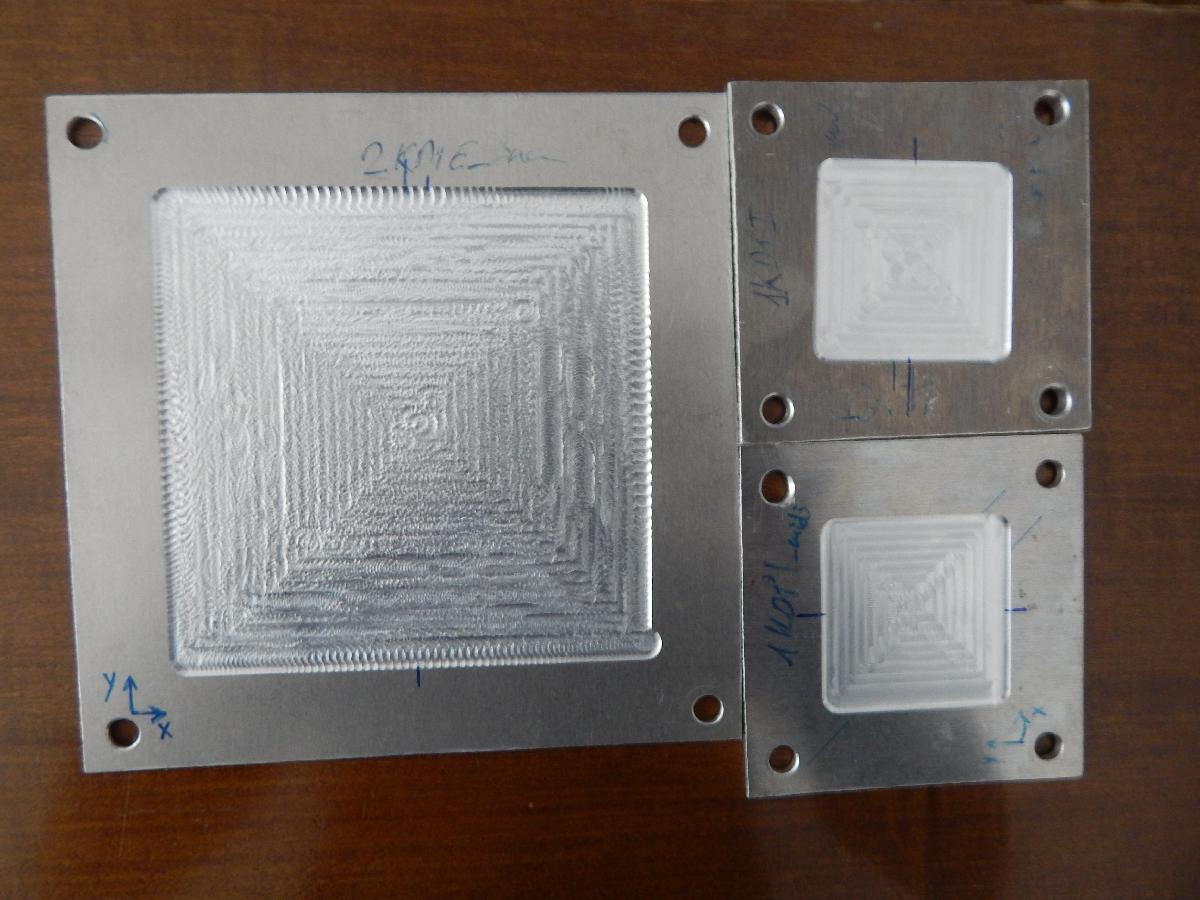    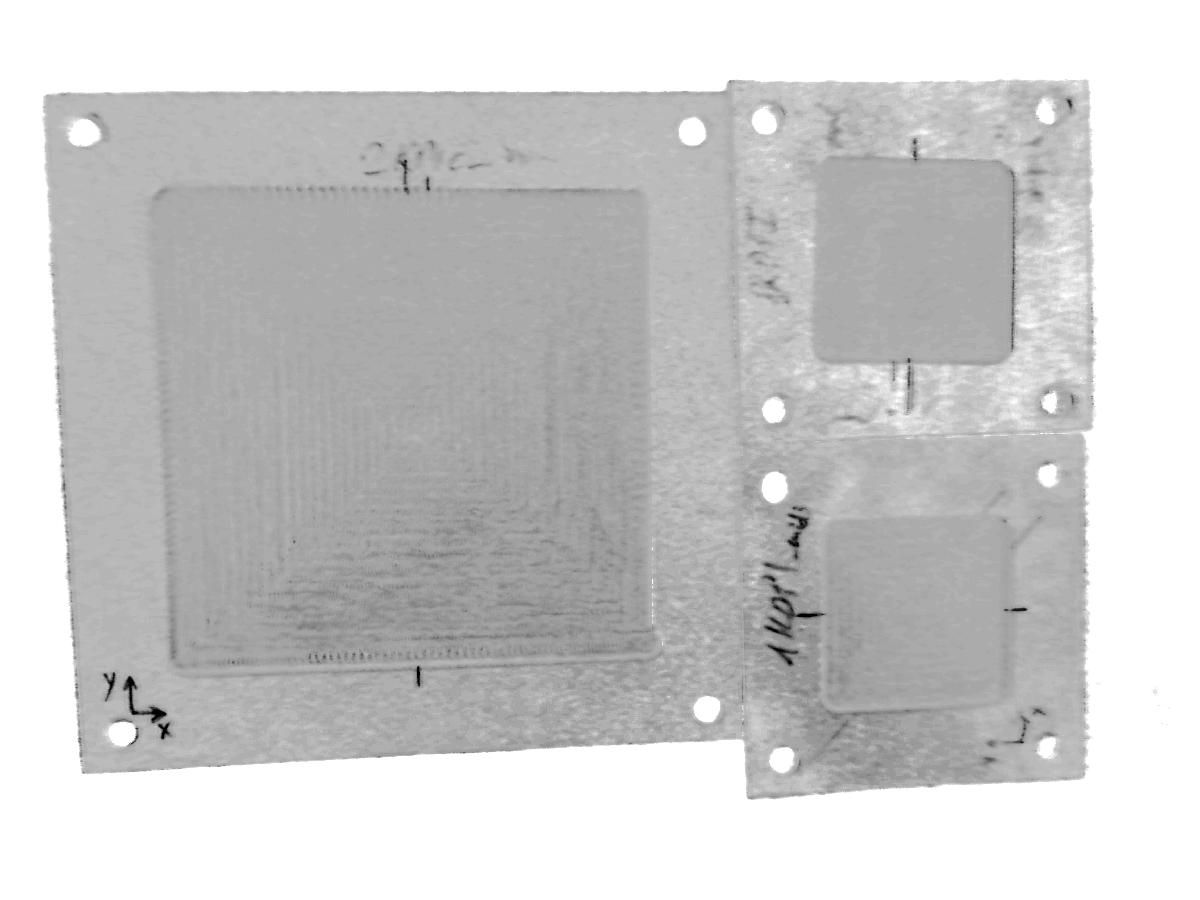

## Referencias

- Álvarez, J. M., & López, A. M. "Road detection based on illuminant invariance," *IEEE Transactions on Intelligent Transportation Systems*, vol. 12, no. 1, pp. 184-193, Mar. 2011.